[I, map] = imread('C:\dev\biomedeng\Associated Files\Chapter 14\blood1.tif')

I = 265×272 uint8 matrix
    46    46    48    56    73    85    96    96   106   113   118   126   131   143   165   171   160   131    85    46    46    46    46    46    46    46    46    46    46    48   101   138   160   181   171   176   160   160   148   155   155   155   155   160   155   155   155   155   155   148
    46    46    48    56    68    80    85   101   101   113   123   126   138   148   165   176   155   123    63    48    46    46    46    46    46    46    46    46    46    46    85   131   155   181   171   176   160   155   143   143   148   148   155   155   155   160   148   155   148   148
    46    46    46    55    68    80    80    90   101   106   113   123   126   143   148   165   143   113    56    46    46    46    46    46    46    46    46    46    46    46    85   131   155   176   171   165   155   155   143   155   148   148   155   148   148   148   155   155   155   155
    46    46    46    48    55    63    73    90   101   106   113   118


map =

     []



I = im2double(I)

I =     0.1804    0.1804    0.1882    0.2196    0.2863    0.3333    0.3765    0.3765    0.4157    0.4431    0.4627    0.4941    0.5137    0.5608    0.6471    0.6706    0.6275    0.5137    0.3333    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1882    0.3961    0.5412    0.6275    0.7098    0.6706    0.6902    0.6275    0.6275    0.5804    0.6078    0.6078    0.6078    0.6078    0.6275    0.6078    0.6078    0.6078    0.6078    0.6078    0.5804
    0.1804    0.1804    0.1882    0.2196    0.2667    0.3137    0.3333    0.3961    0.3961    0.4431    0.4824    0.4941    0.5412    0.5804    0.6471    0.6902    0.6078    0.4824    0.2471    0.1882    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.3333    0.5137    0.6078    0.7098    0.6706    0.6902    0.6275    0.6078    0.5608    0.5608    0.5804    0.5804    0.6078    0.6078    0.6078    0.6275    0.5804    0.6078    0.5804    0


b1 = fspecial('gaussian', [20 20], 0.4)

b1 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

b2 = fspecial('gaussian', [20 20], 4)

b2 =     0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0006    0.0006    0.0006    0.0006    0.0005    0.0004    0.0003    0.0002    0.0002    0.0001    0.0001    0.0000
    0.0001    0.0001    0.0002    0.0003    0.0004    0.0006    0.0007    0.0009    0.0010    0.0011    0.0011    0.0010    0.0009    0.0007    0.0006    0.0004    0.0003    0.0002    0.0001    0.0001
    0.0001    0.0002    0.0003    0.0005    0.0007    0.0009    0.0012    0.0014    0.0016    0.0017    0.0017    0.0016    0.0014    0.0012    0.0009    0.0007    0.0005    0.0003    0.0002    0.0001
    0.0002    0.0003    0.0005    0.0007    0.0011    0.0014    0.0019    0.0022    0.0025    0.0027    0.0027    0.0025    0.0022    0.0019    0.0014    0.0011    0.0007    0.0005    0.0003    0.0002
    0.0002    0.0004    0.0007    0.0011    0.0015    0.0021    0.0027    0.0033    0.0037    0.0039    0.0039    0.0037    0.0033    0.0027    0.0021    0.0015    0.0011    0.0007    0.0004 


I_f1 = imfilter(I, b1)

I_f1 =     0.1801    0.1842    0.2038    0.2478    0.2997    0.3388    0.3702    0.3957    0.4241    0.4574    0.4829    0.5103    0.5485    0.6082    0.6629    0.6482    0.5571    0.3937    0.2372    0.1823    0.1802    0.1802    0.1802    0.1802    0.1802    0.1802    0.1802    0.1802    0.1823    0.2744    0.4455    0.5719    0.6629    0.6895    0.6797    0.6581    0.6220    0.5936    0.5770    0.5886    0.5935    0.6004    0.6121    0.6121    0.6121    0.6053    0.6004    0.6004    0.5867    0.5750
    0.1802    0.1824    0.2010    0.2421    0.2901    0.3186    0.3490    0.3853    0.4128    0.4461    0.4755    0.5029    0.5441    0.5921    0.6410    0.6263    0.5234    0.3482    0.2091    0.1824    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1804    0.1805    0.2571    0.4236    0.5608    0.6538    0.6852    0.6696    0.6432    0.6128    0.5844    0.5726    0.5824    0.5804    0.5941    0.6010    0.5942    0.5990    0.5990    0.6010    0.6010    0.5941  

I_f2 = imfilter(I, b2)

I_f2 =     0.0807    0.0981    0.1162    0.1346    0.1533    0.1720    0.1904    0.2083    0.2250    0.2400    0.2523    0.2616    0.2669    0.2676    0.2630    0.2534    0.2395    0.2223    0.2035    0.1847    0.1681    0.1549    0.1464    0.1433    0.1458    0.1542    0.1684    0.1877    0.2112    0.2372    0.2638    0.2892    0.3119    0.3306    0.3448    0.3547    0.3608    0.3640    0.3652    0.3653    0.3646    0.3636    0.3627    0.3619    0.3611    0.3604    0.3596    0.3589    0.3581    0.3574
    0.0920    0.1117    0.1320    0.1526    0.1735    0.1944    0.2150    0.2350    0.2537    0.2706    0.2845    0.2951    0.3014    0.3025    0.2979    0.2877    0.2726    0.2540    0.2334    0.2129    0.1947    0.1804    0.1714    0.1685    0.1721    0.1824    0.1993    0.2220    0.2493    0.2793    0.3097    0.3386    0.3641    0.3850    0.4008    0.4117    0.4183    0.4217    0.4229    0.4229    0.4220    0.4209    0.4198    0.4189    0.4181    0.4172    0.4164    0.4155    0.4146  


t1 = graythresh(I_f1)

t1 = 0.4392

t2 = graythresh(I_f2)

t2 = 0.4627

I_t1 = im2bw(I_f1, t1)

I_t1 = 265×272 logical array
   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   

I_t2 = im2bw(I_f2, t2)

I_t2 = 265×272 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   

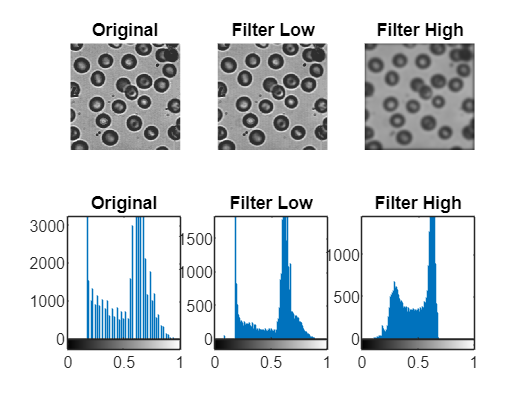


subplot(2, 3, 1)
imshow(I)
title('Original')
subplot(2, 3, 2)
imshow(I_f1)
title('Filter Low')
subplot(2, 3, 3)
imshow(I_f2)
title('Filter High')
subplot(2, 3, 4)
imhist(I)
title('Original')
subplot(2, 3, 5)
imhist(I_f1)
title('Filter Low')
subplot(2, 3, 6)
imhist(I_f2)
title('Filter High')

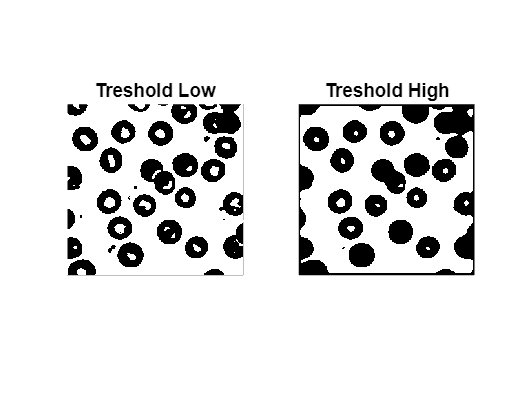

figure;

subplot(1, 2, 1)
imshow(I_t1)
title('Treshold Low')
subplot(1, 2, 2)
imshow(I_t2)
title('Treshold High')